# Sistemas de ecuaciones no lineales

## Algoritmo de Newton multivariable

syms x1 x2 x3
f1=3*x1-cos(x2*x3)-1/2;
f2=x1^2-81*(x2+0.1)^2+sin(x3)+1.06;
f3=exp(-x1*x2)+20*x3+(10*pi-3)/3;
F=[f1 f2 f3]';
X0=[-1 1 0];
[X1,err]=newton_multivariable(F,X0,10e-6,10)

El error está dentro de la tolerancia indicada


X1 =     0.5000
    0.0000
   -0.5236


err = 1.3396e-06

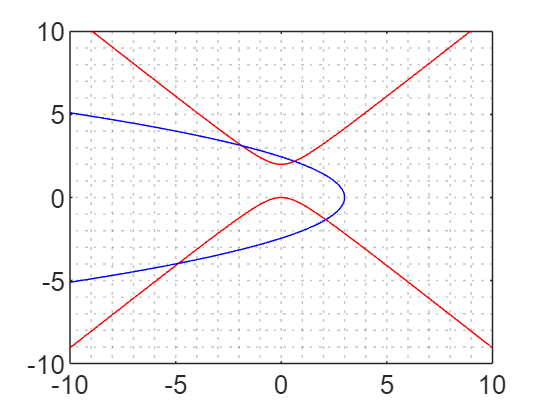

f1=x1^2-x2^2+2*x2;
f2=2*x1+x2^2-6;
F=[f1 f2]';
fimplicit(f1,[-10 10],'r')
hold on
fimplicit(f2,[-10 10],'b')
grid minor
hold off

X0=[0.5 2.2];
[X1,err]=newton_multivariable(F,X0,10e-10,100)

El error está dentro de la tolerancia indicada


X1 =     0.6252
    2.1794


err = 1.9710e-10

X0=[2.5 -0.9];
[X1,err]=newton_multivariable(F,X0,10e-10,100)

El error está dentro de la tolerancia indicada


X1 =     2.1095
   -1.3345


err = 1.8273e-14

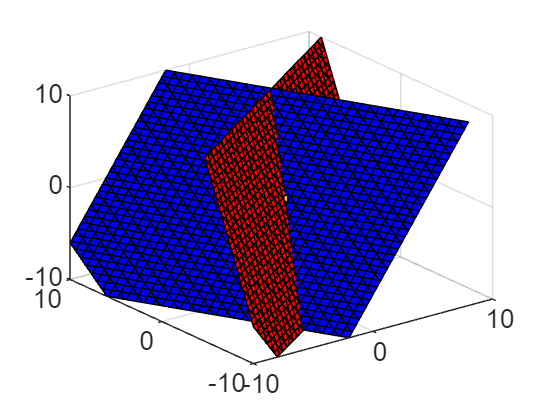

f1=2*x1-3*x2+x3-4;
f2=2*x1+x2-x3+4;
f3=x1^2+x2^2+x3^2-4;
F=[f1 f2 f3]';
fimplicit3(f1,[-10 10],'r')
hold on
fimplicit3(f2,[-10 10],'b')
fimplicit3(f3,[-10 10],'y')
hold off

X0=[-0.82 -1.76 0.58]

X0 =    -0.8200   -1.7600    0.5800


[X1,err]=newton_multivariable(F,X0,10e-10,20)

El error está dentro de la tolerancia indicada


X1 =    -0.8571
   -1.7143
    0.5714


err = 3.8503e-10

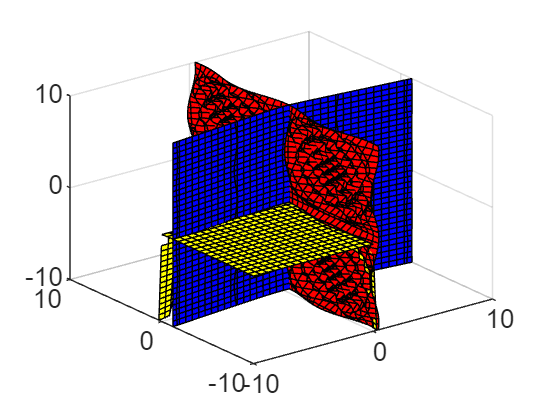

f1=6*x1-2*cos(x2*x3)-1;
f2=9*x2+sqrt(x1^2+sin(x3)+1.06)+0.9;
f3=60*x3+3*exp(-x1*x2)+10*pi-3;
F=[f1 f2 f3]';
fimplicit3(f1,[-10 10],'r')
hold on
fimplicit3(f2,[-10 10],'b')
fimplicit3(f3,[-10 10],'y')
hold off

X0=[0.58 -0.2 -0.58];
[X1,err]=newton_multivariable(F,X0,10e-10,20)

El error está dentro de la tolerancia indicada


X1 =     0.4981
   -0.1996
   -0.5288


err = 2.7756e-17

syms x1 x2 x3 x4 x5 x6
f1=x1*x2+x6*x4-18;
f2=x2+x5+x6-12;
f3=x1+log(x2/x4)-2;
f4=x3^2+x3-2;
f5=x2+x4-4;
f6=x3*(x3+6)-7;
F=[f1 f2 f3 f4 f5 f6]';
X0=[1 1 1 1 1 1];
[X1,err]=newton_multivariable(F,X0,10e-10,20)

El error no está dentro de la tolerancia indicada, pueden necesitarse más iteraciones


X1 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


err =    NaN


X0=[1 2 3 4 5 6];
[x,fx]=fsolve(@P4_2,X0)


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.000000e+02.



x =    2.444048346499238   1.578035493242353   0.999622864946965   2.488049443384240   4.741822183831952   5.679891528585363


fx =   -0.011354005844243
  -0.000250794340332
  -0.011269986203348
  -0.001131262928256
   0.066084936626593
  -0.003016938193431


syms x1 x2 x3 x4 x5 x6 
f1=x1*x2+x6*x4==18;
f2=x2+x5+x6==12

$$f2 = x_{2}+x_{5}+x_{6}=12$$

f3=x1+log(x2/x4)==2;
f4=x3^2+x3==2;
f5=c;
f6=x3*(x3+6)==7;
F=[f1 f2 f3 f4 f5 f6]; 
sol=vpasolve(F,[1 1 1 1 1 1])

sol = struct with fields:
    x1: 2.2212496774028417508877821680645
    x2: 1.7796484667955552528020755993567
    x3: 1.0
    x4: 2.2203515332044447471979244006435
    x5: 3.8938954711019126905887923155971
    x6: 6.3264560621025320566091320850462


class(sol)

ans = 'struct'

sol=struct2table(sol)

sol = 1×6 table
                   x1                                   x2                    x3                    x4                                   x5                                   x6                
    _________________________________    _________________________________    ___    _________________________________    _________________________________    _________________________________

    2.2212496774028417508877821680645    1.7796484667955552528020755993567    1.0    2.2203515332044447471979244006435    3.8938954711019126905887923155971    6.3264560621025320566091320850462


sol=table2array(sol)

$$sol = \left(\begin{array}{cccccc} 2.2212496774028417508877821680645 & 1.7796484667955552528020755993567 & 1.0 & 2.2203515332044447471979244006435 & 3.8938954711019126905887923155971 & 6.3264560621025320566091320850462 \end{array}\right)$$

sol=double(sol)

sol =     2.2212    1.7796    1.0000    2.2204    3.8939    6.3265


sol=sol'

sol =     2.2212
    1.7796
    1.0000
    2.2204
    3.8939
    6.3265



syms x1 x2 x3
f1='3*x1-cos(x2*x3)-1/2'

f1 = '3*x1-cos(x2*x3)-1/2'

str2sym(f1)

$$ans = 3\,x_{1}-\cos\left(x_{2}\,x_{3}\right)-\frac{1}{2}$$